N=[123 12 3 43; 134 13 133 12; 135 34 56 6;3 465 43 90];
a=length(N)

a = 4

first=1;
second=1;
for i=1:(N-2)   %The index has to have two terms removed because it starts with 1 and 1 already
        next=first+second;  %The current term in the series is a summation of the previous two terms
        first=second;   %Each term must by iterated upwards by an index of one
        second=next;    %The term that previously was second is now referred to as next
end
for i=1:length(N)
    disp([N(i) next])
end

   1.0e+25 *

    0.0000    2.2698

   1.0e+25 *

    0.0000    2.2698

   1.0e+25 *

    0.0000    2.2698

   1.0e+25 *

    0.0000    2.2698



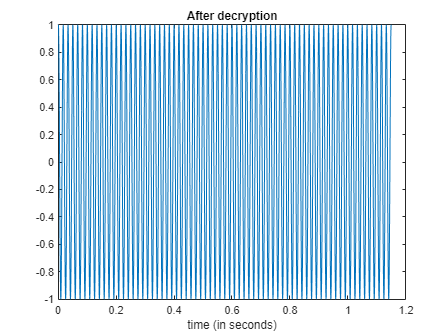

   %%Time specifications:
   Fs = 8000+1000*N(i,a);                   % samples per second
   dt = 1/Fs;                   % seconds per sample
   StopTime = 0.25+(N(i,a)/100);             % seconds
   t = (0:dt:StopTime-dt)';     % seconds

   %%Sine wave:
   Fc = 60;                     % hertz
   x = cos(2*pi*Fc*t);

   % Plot the signal versus time:
   figure;
   plot(t,x);
   xlabel('time (in seconds)');
   title('After decryption');
   zoom xon;

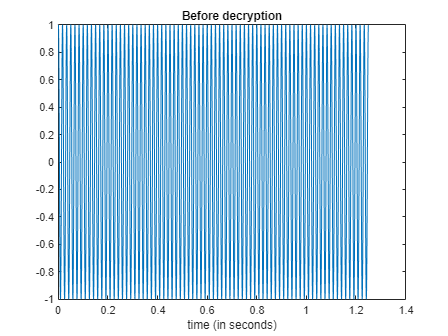

 %%Time specifications:
   Fs = 8000+N(i,a);                   % samples per second
   dt = 1/Fs;                   % seconds per sample
   StopTime = 0.25+(N(i,a)/90);             % seconds
   t = (0:dt:StopTime-dt)';     % seconds

   %%Sine wave:
   Fc = 60;                     % hertz
   x = cos(2*pi*Fc*t);

   % Plot the signal versus time:
   figure;
   plot(t,x);
   xlabel('time (in seconds)');
   title('Before decryption');
   zoom xon;